## P3 控制系统的模型与分析

## 3.1 系统的数学模型

控制设计过程的第一步是建立被控系统的适当数学模型。这些模型既可以基于物理定律推导，也可以基于实验数据建立。

**动态系统**是随时间按照某种确定规律变化或演化的系统。许多物理系统都可以表示为一组一阶微分方程：

$\dot{x}=f(x,u,t)
$  (1)

在上式中，$$x(t)$$ 是**状态向量**，即一组表示系统在时间 $$t$$ 时的配置的变量。例如，在一个简单的机械质量-弹簧-阻尼系统中，两个状态变量可以是质量的位置和速度。$$u(t)$$ 是系统在时间 $$t$$ 处的外部输入向量，而 $$f$$ 是一个（可能是非线性的）函数，它生成状态向量在特定时刻的时间导数（变化率）$$dx/dt$$。

与前文的常微分方程求解不同，此处的系统模型增加输入项，

然而，当设计完$u(t)
$，即$u(t)
$已知，闭环系统可以写成标准的一阶常微分方程。

### 3.1.1 引例 

#### 质量块-弹簧-阻尼器系统

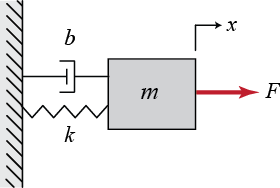

弹簧力与质点的位移 $x$ 成正比，粘性阻尼力与质点的速度 $v=\dot{x}$ 成正比。这两股力都与质点的运动方向相反，因此均表示为负 $x$ 方向。另请注意，$x=0$ 对应于弹簧未拉伸时质点的位置。

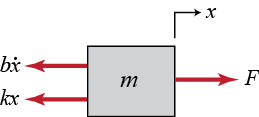

现在，我们通过求和各方向上的力，并应用牛顿第二定律来分析。


$$m \ddot{x} + b \dot{x} + k x = F$$


令系统状态表示为，$z = (x,\dot{x})$。此情况下的状态方程为：


$$\dot{z} = \left[ \begin{array}{c} \dot{x} \\ \ddot{x} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{k} {m}  & -\frac{b}{m} \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right] + \left[ \begin{array}{c} 0 \\ \frac{1}{m} \end{array} \right] F(t)
$$


如果我们要控制质量的位置，则输出方程为：


$$y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right]$$
 

现在，演示如何将上面推导出的方程输入到Matlab

定义参数

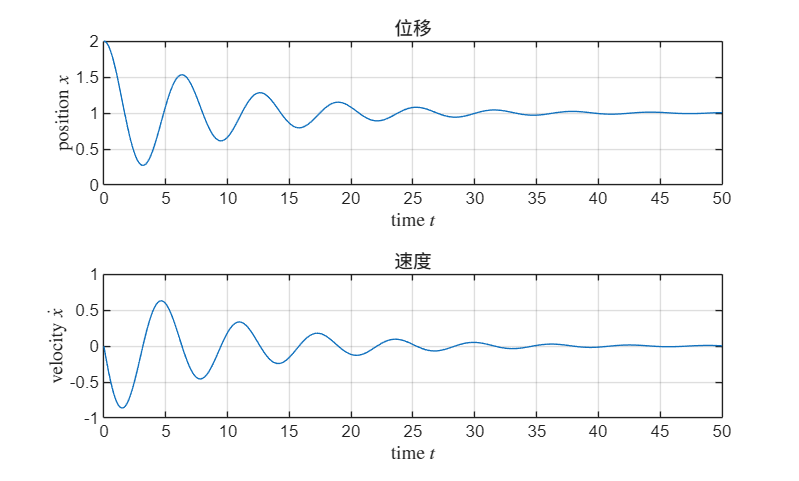

% 定义参数
m = 1;
k = 1;
b = 0.2;
F = 1;

% 定义系统方程
% 
msd_dyn = @(~,x) [x(2); -(k/m)*x(1)-(b/m)*x(2)+F/m];

% 设置相对误差和绝对误差
odeOptions = odeset('RelTol',1e-5,'AbsTol',1e-4);
tspan = [0, 50];
x0 = [2 0].';
[t_msd, x_msd] = ode45(msd_dyn, tspan, x0, odeOptions);


figure()
tiledlayout(2,1)
nexttile
plot(t_msd,x_msd(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('位移')

nexttile
plot(t_msd,x_msd(:,2))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('velocity $\dot{x}$','Interpreter','latex')
title('速度')

#### RLC 无源网络

如图为由电阻R、电感L和电容C组成的无源网络。由基尔霍夫定律可得回路方程：


$$LC \ddot{u}_o + RC \dot{u}_o + u_o = u_i$$


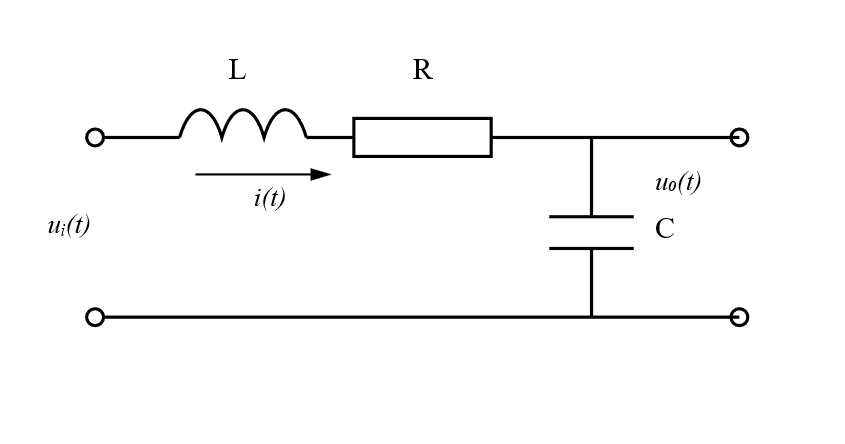

令系统状态表示为，$z = (u_o,\dot{u}_o) = (x, \dot{x})$。此情况下的状态方程为：


$$\dot{z} = \left[ \begin{array}{c} \dot{x} \\ \ddot{x} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{1} {LC}  & -\frac{R}{L} \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right] + \left[ \begin{array}{c} 0 \\ \frac{1}{LC} \end{array} \right] u_i
$$


如果我们要控制电容的电压，则输出方程为：


$$y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right]$$
 

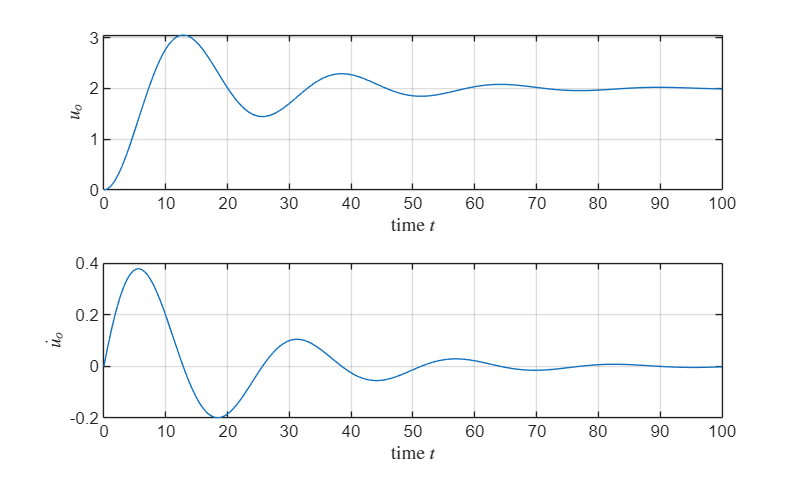

% 定义参数
R = 0.1;
L = 1;
C = 16;
u_i = 2;

% 定义系统方程
% 
rlc_dyn = @(~,x) [x(2); -(1/L/C)*x(1)-(R/L)*x(2)+u_i/L/C];

% 设置相对误差和绝对误差
odeOptions = odeset('RelTol',1e-5,'AbsTol',1e-4);
tspan = [0, 100];
x0 = [0 0].';
[t_rlc, x_rlc] = ode45(rlc_dyn, tspan, x0, odeOptions);


figure()
tiledlayout(2,1)
nexttile
plot(t_rlc,x_rlc(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('${u_o}$','Interpreter','latex')

nexttile
plot(t_rlc,x_rlc(:,2))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('$\dot{u}_o$','Interpreter','latex')

虽然方程（1）给出的关系非常通用，可用于描述各种各样的系统；但遗憾的是，该关系可能非常难以分析。有两种常见的简化方法，可使问题更易于处理。

- 如果函数 $f
$ 不显式依赖于时间，即 $\dot{x} = f(x,u)$，则称该系统为**时不变系统**。这是一个非常合理的假设，因为基本的物理定律本身通常不随时间变化。对于时不变系统，函数 $f
$ 的参数或系数是常量。

- 第二个常见的假设涉及系统的**线性性**。实际上，几乎所有物理系统都是非线性的。换句话说，$f
$ 通常是状态和输入的某个复杂函数。这些非线性现象的产生方式多种多样，其中在控制系统中最常见的一种是“饱和”，即系统中的某个元件达到了其工作的硬性物理极限。幸运的是，在足够小的运行范围内（可理解为曲线附近的切线），大多数系统的动力学行为近似呈**线性**。在这种情况下，一阶微分方程组可以表示为矩阵方程，即 $\dot{x} = Ax + Bu$。

在数字计算机问世之前（以及此后相当长的一段时间内），只有**线性时不变（LTI）**系统的分析才是切实可行的。因此，控制理论的大部分成果都是基于这些假设的。

### 3.1.2 线性系统

线性系统满足**叠加性**和**齐次性**。

- **叠加性：**两个外作用同时加于系统所产生的总输出，等于各个外作用单独作用时分别产生的输出之和。

- **齐次性：**外作用的数值增大若干倍时，其输出亦相应增大相同的倍数。

例如：设微分方程


$$\ddot{x} (t) + c_1 \dot{x} (t) + c_2 = f(t)$$


当输入为$f_i(t)$时，方程的解是$x_i(t)$，$i = 1,2,3$。那么

- 如果输入为 $f(t) = f_1 (t) + f_2 (t) $, 方程的解为 $x_1(t) + x_2 (t)$

- 如果输入为 $f(t) = a f_1 (t)  $, $a$ 是常数,方程的解为 $a x_1(t)$

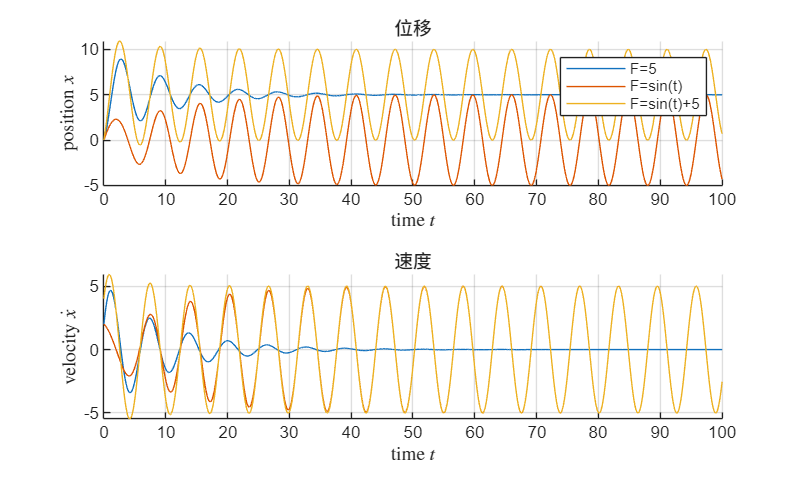

% 继续考虑 质量块-弹簧-阻尼器系统


% 输入 F = 5,
% 
msd_dyn_1 = @(~,x) [x(2); -(k/m)*x(1)-(b/m)*x(2)+5/m];

% 输入 F = sin(t)
msd_dyn_2 = @(t,x) [x(2); -(k/m)*x(1)-(b/m)*x(2)+sin(t)/m];

% 输入 F = sin(t) +5
msd_dyn_3 = @(t,x) [x(2); -(k/m)*x(1)-(b/m)*x(2)+(sin(t)+5)/m];

% 输入 F = 3*sin(t)
msd_dyn_4 = @(t,x) [x(2); -(k/m)*x(1)-(b/m)*x(2)+3*sin(t)/m];


% 注意：在验证叠加性和齐次性时，初始条件也要同样做线性叠加
tspan = [0, 100];
x0 = [0 2].';

sol_1 = ode45(msd_dyn_1, tspan, x0, odeOptions);
sol_2 = ode45(msd_dyn_2, tspan, x0, odeOptions);
sol_3 = ode45(msd_dyn_3, tspan, 2*x0, odeOptions);
sol_4 = ode45(msd_dyn_4, tspan, x0*3, odeOptions);


% 利用ode45求得的解，针对以下时间序列，进行插值，得到对应的数值解
t = (0:0.01:100).';

x1 = deval(sol_1,t).';
x2 = deval(sol_2,t).';
x3 = deval(sol_3,t).';
x4 = deval(sol_4,t).';

% 画图
figure()
tiledlayout(2,1)
nexttile
hold on 
plot(t, x1(:,1))
plot(t, x2(:,1))
plot(t, x3(:,1))
% plot(t, x4(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
legend({'F=5','F=sin(t)','F=sin(t)+5'})
title('位移')

nexttile
hold on 
plot(t, x1(:,2))
plot(t, x2(:,2))
plot(t, x3(:,2))
% plot(t, x4(:,2))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('velocity $\dot{x}$','Interpreter','latex')
title('速度')

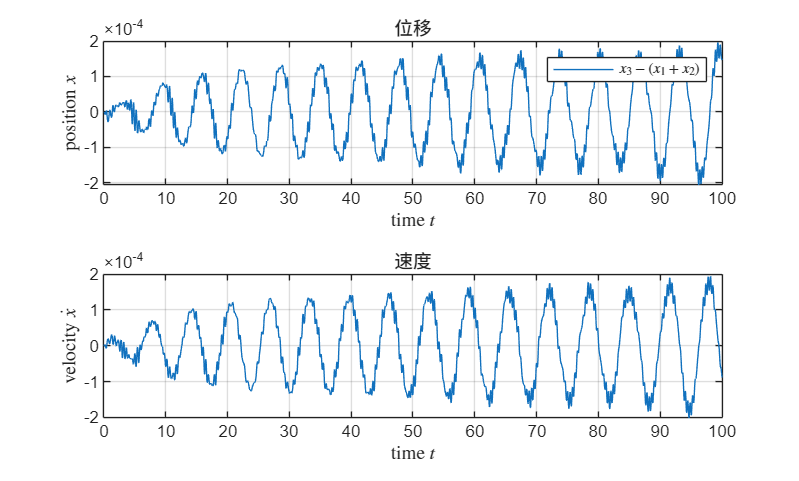


% 叠加
figure()
tiledlayout(2,1)
nexttile
plot(t, x3(:,1)-x1(:,1)-x2(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
legend({'$x_3 - (x_1 + x_2)$'},'Interpreter','latex')
title('位移')

nexttile
plot(t, x3(:,2)-x1(:,2)-x2(:,2))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('velocity $\dot{x}$','Interpreter','latex')
title('速度')

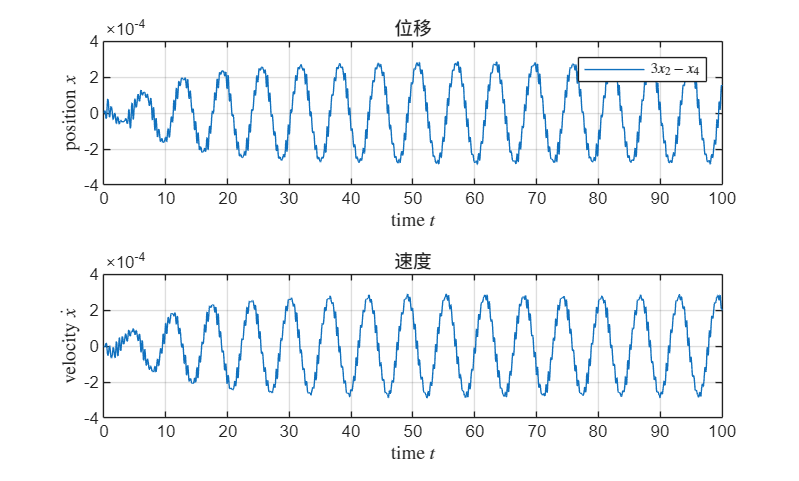


% 齐次
figure()
tiledlayout(2,1)
nexttile
plot(t, 3*x2(:,1)-x4(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
legend({'$3x_2 - x_4$'},'Interpreter','latex')
title('位移')

nexttile
plot(t, 3*x2(:,2)-x4(:,2))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('velocity $\dot{x}$','Interpreter','latex')
title('速度')

## 3.2 状态空间法

对于连续线性时不变（LTI）系统，其标准状态空间表示形式如下：

$$$
\dot{x} = Ax + B u
$$$  (2)

$y = Cx + Du$  (3)

其中 $x\in \mathbb{R}^{n}$ 是状态变量，$\dot{x}\in \mathbb{R}^{n}$ 是状态的变化率，$u \in \mathbb{R}^{m}$是输入或控制向量（p×1），$y\in \mathbb{R}^{p}$ 是输出向量，$A \in \mathbb{R}^{n \times n}$是系统矩阵， $B \in \mathbb{R}^{n \times m}$为输入矩阵，$C \in \mathbb{R}^{p \times n}$为输出矩阵，$D \in \mathbb{R}^{p \times m}$ 为前馈矩阵。

MATLAB 内置成套线性系统分析工具，可直接用于系统分析。下面进行介绍。

### 3.2.1 引例

#### 质量块-弹簧-阻尼器系统

弹簧力与质点的位移 $x$ 成正比，粘性阻尼力与质点的速度 $v=\dot{x}$ 成正比。这两股力都与质点的运动方向相反，因此均表示为负 $x$ 方向。另请注意，$x=0$ 对应于弹簧未拉伸时质点的位置。

现在，我们通过求和各方向上的力，并应用牛顿第二定律来分析。令系统状态表示为，$z = (x,\dot{x})$。此情况下的状态方程为：


$$\dot{z} = \left[ \begin{array}{c} \dot{x} \\ \ddot{x} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{k} {m}  & -\frac{b}{m} \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right] + \left[ \begin{array}{c} 0 \\ \frac{1}{m} \end{array} \right] F(t)
$$


如果我们要控制质量的位置，则输出方程为：


$$y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right]$$
 

现在，演示如何将上面推导出的方程输入到Matlab

定义参数

m = 1;
k = 1;
b = 0.2;
% F = 1;

A = [0 1; -k/m -b/m];
B = [0 1/m]';
C = [1 0];
D = 0;

msd_sys = ss(A,B,C,D)


msd_sys =
 
  A = 
         x1    x2
   x1     0     1
   x2    -1  -0.2
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
连续时间状态空间模型。


线性时不变系统的模型建立，命令 ss().

### **3.2.2 时域响应**

**时域响应**描述了动态系统在受到特定输入时，其状态随时间的变化情况。由于我们推导出的模型由微分方程组成，因此必须进行积分运算才能确定系统的时域响应。

线性动态系统的时间响应由两部分组成：取决于初始条件的**瞬态响应**，以及取决于系统输入的**稳态响应**。它们分别对应于控制微分方程的齐次解（自由输入或零输入）和特解。

本小节依然以质量块-弹簧-阻尼器系统为例

#### a. 阶跃响应

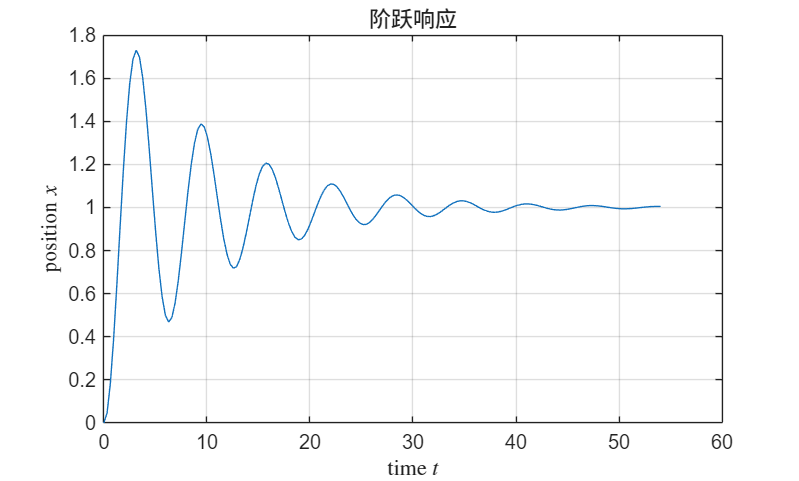

% step：动态系统的阶跃响应
% 输入力为 1N，初始条件为0的质-弹-阻系统的输出响应为
Config = RespConfig(Amplitude=1);
[z,tOut] = step(msd_sys, Config);

figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('阶跃响应')

请和3.1节使用 ode45 对比，观察轨迹是否一样。

典阶跃响应指标：

- **上升时间**：系统阶跃响应第一次从稳态值的10% 上升到 90% 所用时间

- **超调量**：响应峰值超出稳态值的百分比

- **调节时间**（稳态时间）：响应进入稳态值 ±2%（或 ±5%）误差带、且不再跑出区间的最小时间

- **稳态误差**：系统完全稳定后，期望输入值与实际输出的差值

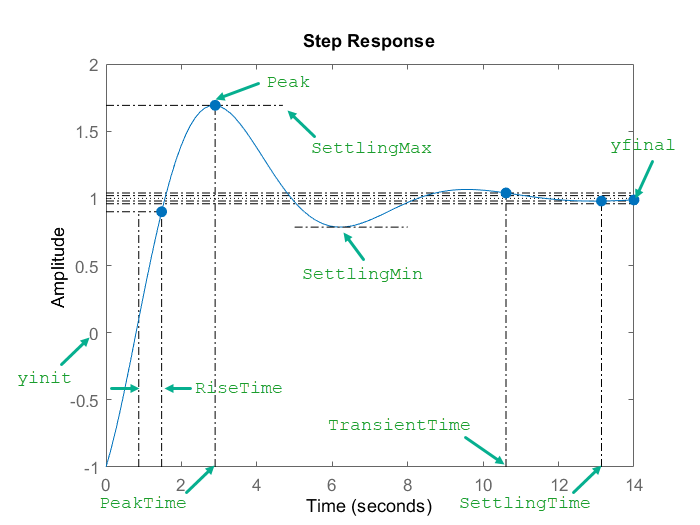

S1 = stepinfo(msd_sys)

S1 = 包含以下字段的 struct:
         RiseTime: 1.1272
    TransientTime: 38.3730
     SettlingTime: 38.3730
      SettlingMin: 0.4685
      SettlingMax: 1.7292
        Overshoot: 72.9156
       Undershoot: 0
             Peak: 1.7292
         PeakTime: 3.1416


#### b. 冲激响应

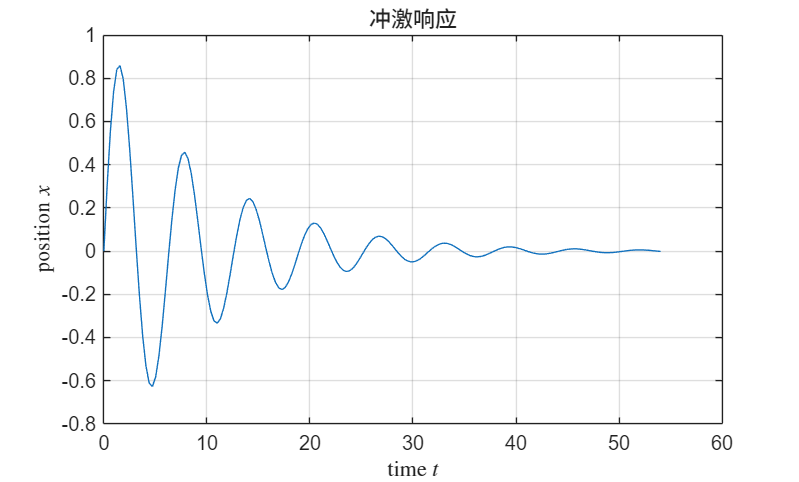

[z,tOut] = impulse(msd_sys);

figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('冲激响应')

可能会有疑问?

**理想狄拉克 **$\delta$** 函数不能直接放进 ode 求解器**，$\delta(t)$ 是广义函数，数值上无法直接采样，那么Matlab是如何计算的呢？

初值条件等效法：

对方程$\dot{x} = A x + B \delta(t)$，从$0^-$到$0^+$积分：


$$x(0^+) - x(0^-) = \int_{0^-}^{0^+}  A x \mathrm{d}t +  \int_{0^-}^{0^+}  B \delta(t) \mathrm{d}t$$


得到


$$x(0^+) = x(0^-) +  B $$


因此，求冲激响应，不需要加输入，直接把初始状态设为 $x(0) = B$，输入 $u = 0$，做零输入仿真！

验证：

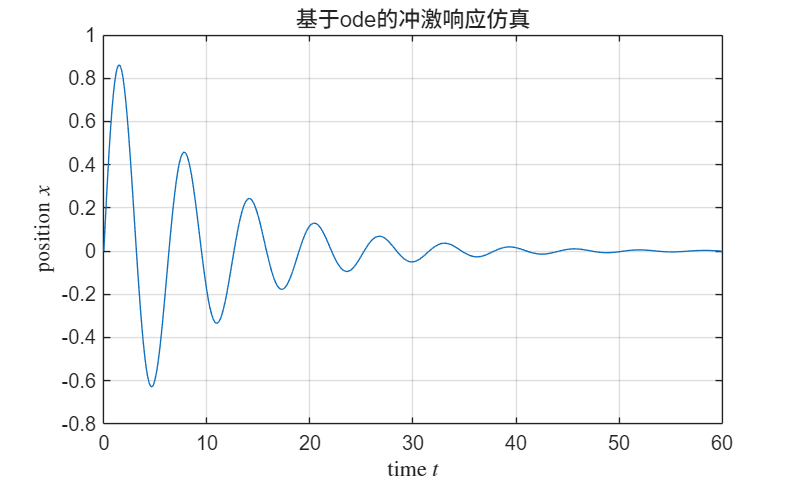

% 定义系统方程
% 
msd_dyn_d = @(~,x) [x(2); -(k/m)*x(1)-(b/m)*x(2)];

tspan = [0, 60];
x0 = [0 1].';
[t_msd, x_msd] = ode45(msd_dyn_d, tspan, x0, odeOptions);


figure()
plot(t_msd,x_msd(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('基于ode的冲激响应仿真')

#### c. 零输入响应

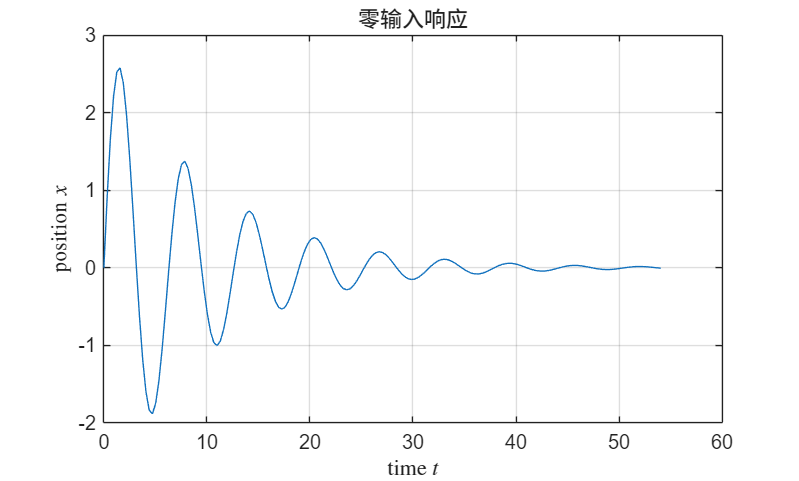

% initial: 系统对状态空间模型的初始状态的零输入响应
z0 = [0 3].';
[z,tOut] = initial(msd_sys, z0);

figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('零输入响应')

#### d. 任意输入的时间响应

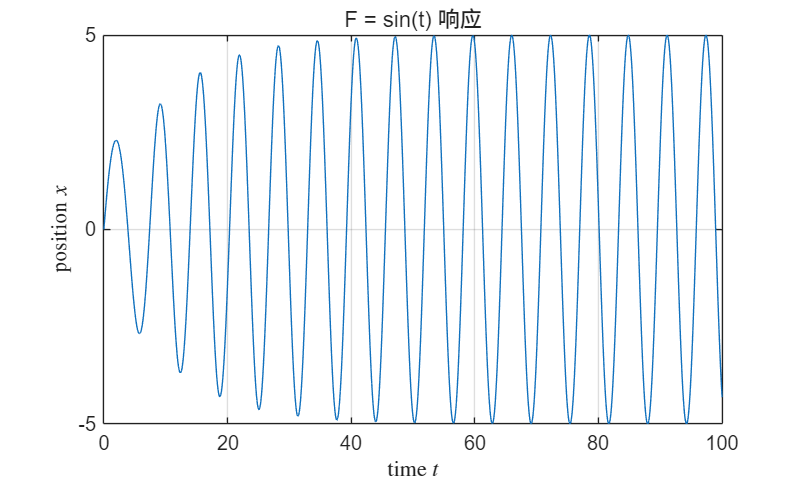

% F = sin(t)
t = (0:0.01:100).';
u = sin(t);

z0 = [0 2].';
[z,tOut] = lsim(msd_sys, u, t, z0);
figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('F = sin(t) 响应')

#### e. 线性系统仿真器

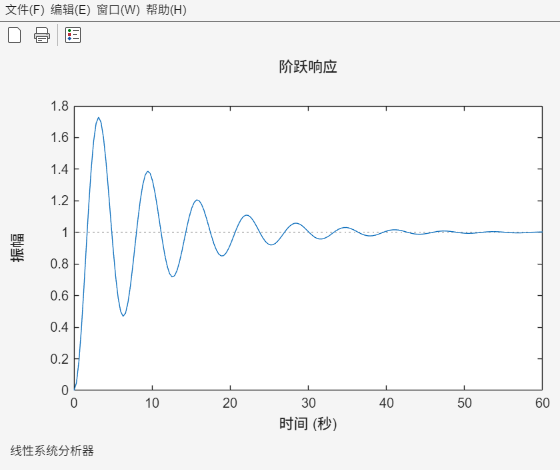

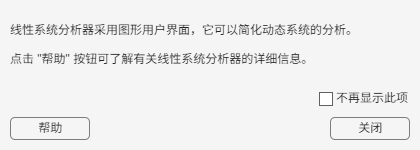

linearSystemAnalyzer(msd_sys)

- 默认情况下，此语法会打开模型的阶跃响应图

- 查看不同类型的响应

- 分析系统性能

详细内容可参考：[线性系统分析器](https://ww2.mathworks.cn/help/releases/R2025b/control/ref/linearsystemanalyzer-app.html)

## 3.3 PID 控制器设计

### 3.3.1 概述

研究以下单位反馈系统：

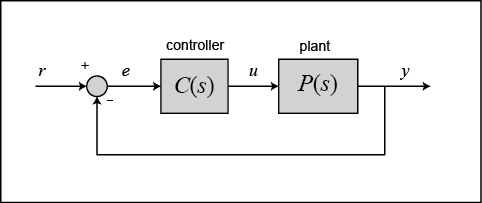

PID 控制器的输出等于被控对象的控制输入，其在时域中根据反馈误差按如下方式计算：


$$u(t) = K_p e(t) + K_i \int e(t)dt + K_p \frac{de}{dt}
$$


首先，让我们通过上图所示的原理图，了解 PID 控制器在闭环系统中的工作原理。

- 变量 ($e$) 代表跟踪误差，即期望输出 ($r$) 与实际输出 ($y$) 之间的差值。

- 该误差信号 ($e$) 被输入到 PID 控制器中，控制器会计算该误差信号随时间的变化率（微分）及其积分。

- 控制信号 ($u$) 等于比例增益 ($K_p$) 乘以误差的绝对值，加上积分增益 ($K_i$) 乘以误差的积分，再加上市差增益 ($K_d$) 乘以误差的导数。

- 该控制信号（$u$）被送入被控对象，从而获得新的输出（$y$）。随后，新的输出（$y$）被反馈回来，并与参考值进行比较，以确定新的误差信号（$e$）。控制器利用该新的误差信号计算出控制输入的更新值。

使用 MATLAB 的 pid 对象来生成一个等效的连续时间控制器，具体如下：

Kp = 1;
Ki = 1;
Kd = 1;

c_pid = pid(Kp,Ki,Kd);
disp(c_pid)

  pid - 属性:

              Kp: 1
              Ki: 1
              Kd: 1
              Tf: 0
        IFormula: ''
        DFormula: ''
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



### 3.3.2 P、I 和 D 项的特性

- 增大比例增益（$K_p$）会使控制信号在相同误差水平下成比例地增大。控制器在给定误差水平下会“更用力地”调节，这往往会使闭环系统响应更快，但也会导致更大的超调量。增大 $K_p$ 的另一个影响是，它往往会减小稳态误差，但无法完全消除。

- 在控制器中加入微分项（$K_d$）使其具备了“预判”误差的能力。在简单的比例控制中，如果 $K_p$ 固定，控制信号只会随着误差的增大而增大。而采用微分控制时，即使误差幅值仍相对较小，只要误差开始呈上升趋势，控制信号就可能变大。这种预判作用往往会为系统增加阻尼，从而减小超调量。不过，添加微分项对稳态误差没有影响。

- 在控制器中加入积分项（$K_i$）通常有助于减小稳态误差。如果存在持续稳定的误差，积分器会不断累积，从而增大控制信号并使误差下降。然而，积分项的一个缺点是它可能会使系统反应更迟钝（并产生振荡），因为当误差信号改变符号时，积分器可能需要一段时间才能“回零”。

### 3.3.3 **例. 简单的质量-弹簧-阻尼系统**

该系统的控制方程为


$$m\ddot{x} + b\dot{x} + kx = F
$$


令系统状态表示为，$z = (x,\dot{x})$。此情况下的状态方程为：


$$\dot{z} = \left[ \begin{array}{c} \dot{x} \\ \ddot{x} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{k} {m}  & -\frac{b}{m} \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right] + \left[ \begin{array}{c} 0 \\ \frac{1}{m} \end{array} \right] F(t)
$$


如果我们要控制质量的位置，则输出方程为：


$$y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right]$$
 

定义参数

m = 1;
k = 20;
b = 10;
F = 1;

A = [0 1; -k/m -b/m];
B = [0 1/m]';
C = [1 0];
D = 0;

msd_sys = ss(A,B,C,D)


msd_sys =
 
  A = 
        x1   x2
   x1    0    1
   x2  -20  -10
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
连续时间状态空间模型。


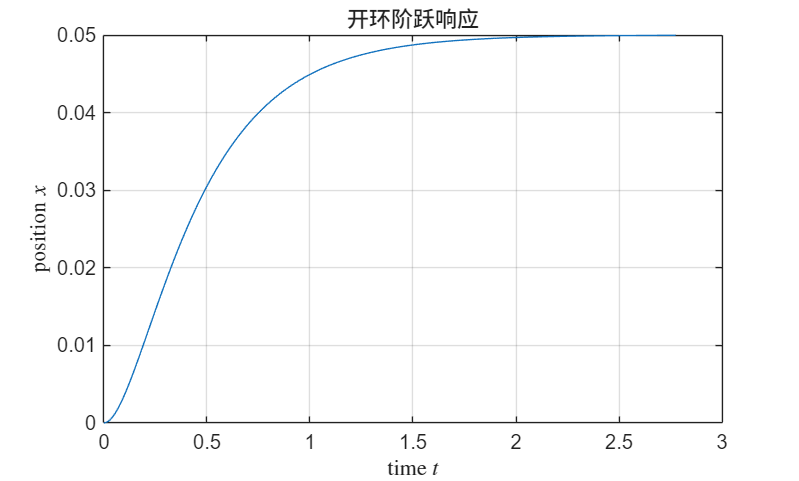


% 开环阶跃响应
[z,tOut] = step(msd_sys);

figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('开环阶跃响应')

对于单位阶阶跃输入，输出最终值为0.05。这对应的稳态误差为0.95，数值相当大。此外，上升时间约为1秒，调节时间约为1.5秒。让我们设计一个控制器，以缩短上升时间、缩短稳态时间并消除稳态误差。

**比例控制**

P控制：从上表可以看出，比例控制器（$K_p$）可以缩短上升时间、增加超调量并减小稳态误差。

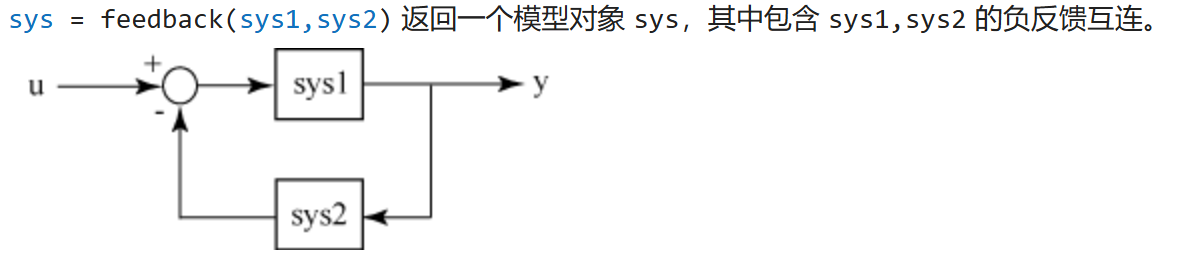

设比例增益 ($$K_p$$) 等于 300

Kp = 300;
c_p = pid(Kp)


c_p =
 
  Kp = 300
 
纯 P 控制器。


clp_1 = feedback(c_p*msd_sys,1,-1)


clp_1 =
 
  A = 
         x1    x2
   x1     0     1
   x2  -320   -10
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
        x1   x2
   y1  300    0
 
  D = 
       u1
   y1   0
 
连续时间状态空间模型。


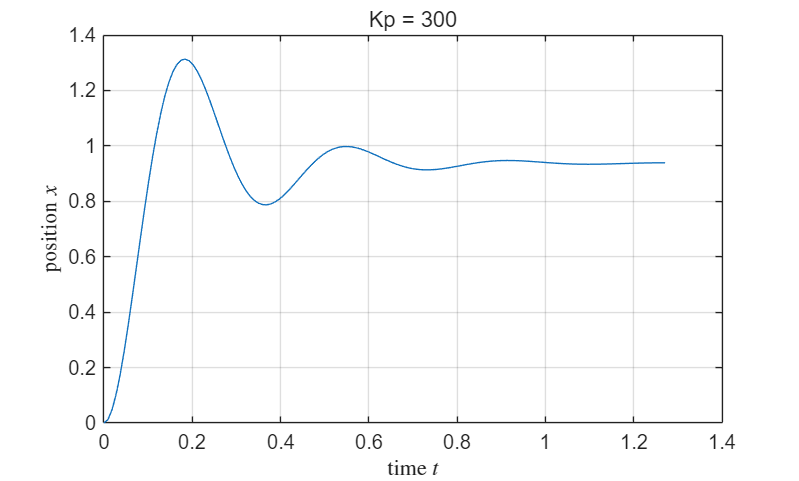


% tspan = 0:0.01:2;
% step(clp_1, tspan)

% P控制
[z,tOut] = step(clp_1);

figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('Kp = 300')

上图显示，比例控制器既缩短了上升时间，又减小了稳态误差，同时增加了超调量，并略微缩短了调节时间。

**比例-微分控制**

PD控制：从上表可以看出，添加微分控制（$K_d$）往往能同时减小超调量和调节时间。

设 $K_p$ 等于 300，$K_d$ 等于 10

Kp = 300;
Kd = 10;
c_pd = pid(Kp, 0, Kd)


c_pd =
 
             
  Kp + Kd * s
             

  且 Kp = 300, Kd = 10
 
并联型的连续时间 PD 控制器。


clp_2 = feedback(c_pd*msd_sys,1,-1)


clp_2 =
 
  A = 
         x1    x2    x3    x4
   x1     1     0     0     0
   x2     0     1    -1     0
   x3     0     0     0     1
   x4   -10     0  -320   -10
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
        x1   x2   x3   x4
   y1   10    0  300    0
 
  D = 
       u1
   y1   0
 
  E = 
       x1  x2  x3  x4
   x1   0   1   0   0
   x2   0   0   0   0
   x3   0   0   1   0
   x4   0   0   0   1
 
连续时间状态空间模型。


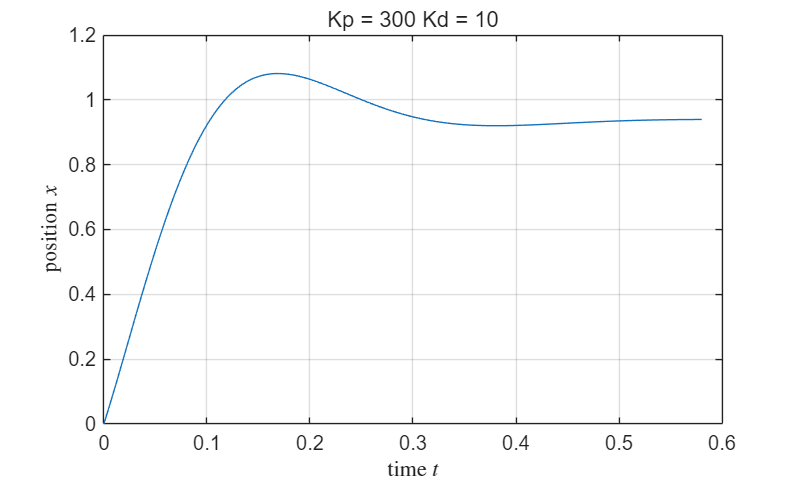

% tspan = 0:0.01:2;
% step(clp_2, tspan)

% PD控制
[z,tOut] = step(clp_2);

figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('Kp = 300 Kd = 10')

上图表明，加入导数项既缩短了超调时间，又缩短了建立时间，而对上升时间和稳态误差的影响可以忽略不计。

**比例-积分控制**

PI控制：加入积分控制（$K_i$）往往会缩短上升时间，同时增加超调量和稳态时间，并减小稳态误差。

将 $K_p$ 设为 25，$K_i$ 设为 70

Kp = 25;
Ki = 70;
c_pi = pid(Kp, Ki)


c_pi =
 
             1 
  Kp + Ki * ---
             s 

  且 Kp = 25, Ki = 70
 
并联型的连续时间 PI 控制器。


clp_3 = feedback(c_pi*msd_sys,1,-1)


clp_3 =
 
  A = 
        x1   x2   x3
   x1    0    1    0
   x2    0    0    1
   x3  -70  -45  -10
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1  70  25   0
 
  D = 
       u1
   y1   0
 
连续时间状态空间模型。


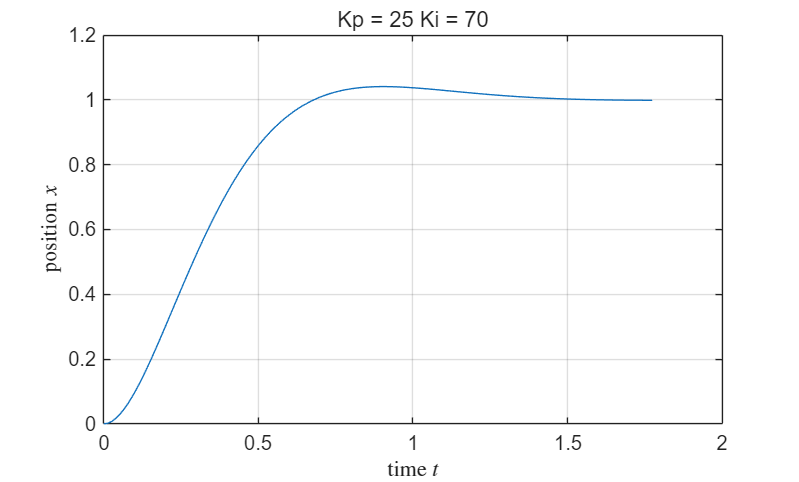

% tspan = 0:0.01:2;
% step(clp_3, tspan)

% PI控制
[z,tOut] = step(clp_3);

figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('Kp = 25 Ki = 70')

注意，我们降低了比例增益（$K_p$），因为积分控制器与比例控制器一样，既会缩短上升时间，又会增加超调量（双重效应）。上图的响应曲线表明，在此情况下，积分控制器消除了稳态误差。

**比例-积分-微分控制**

PID控制：考虑增益 $K_p$ = 300、$K_i$ = 400 和 $K_d$ = 70 产生了期望的响应

Kp = 300;
Ki = 400;
Kd = 70;
c_pid = pid(Kp,Ki,Kd)


c_pid =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  且 Kp = 300, Ki = 400, Kd = 70
 
并联型的连续时间 PID 控制器。


clp_4 = feedback(c_pid*msd_sys,1,-1)


clp_4 =
 
  A = 
         x1    x2    x3    x4    x5
   x1     0     0     0     1     0
   x2     0     1     0     0     0
   x3     0     0     1    -1     0
   x4     0     0     0     0     1
   x5  -400   -70     0  -320   -10
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5   1
 
  C = 
        x1   x2   x3   x4   x5
   y1  400   70    0  300    0
 
  D = 
       u1
   y1   0
 
  E = 
       x1  x2  x3  x4  x5
   x1   1   0   0   0   0
   x2   0   0   1   0   0
   x3   0   0   0   0   0
   x4   0   0   0   1   0
   x5   0   0   0   0   1
 
连续时间状态空间模型。


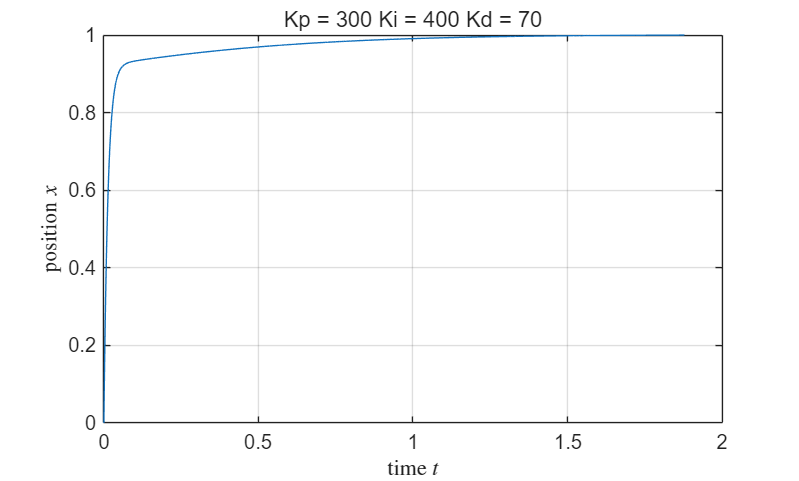


% tspan = 0:0.01:2;
% step(clp_4, tspan)

% PID控制
[z,tOut] = step(clp_4);

figure()
plot(tOut,z(:,1))
grid on
xlabel('time $t$','Interpreter','latex')
ylabel('position ${x}$','Interpreter','latex')
title('Kp = 300 Ki = 400 Kd = 70')

## 3.4 设计PID控制器的一般要点

为给定系统设计PID控制器时，可按以下步骤操作以获得理想的响应。

- 获取开环响应，并确定需要改进的地方

- 添加比例控制以改善上升时间

- 添加微分控制以减少超调

- 添加积分控制以减小稳态误差

- 调整各增益 $K_p$、$K_i$ 和 $K_d$，直至获得理想的整体响应。

最后，请记住，如果没有必要，无需将这三种控制器（比例、微分和积分）全部集成到一个系统中。例如，如果 PI 控制器满足给定要求，则无需在系统中添加微分控制器。请尽可能简化控制器。

**自动PID调参**

MATLAB提供了用于自动选择最佳PID增益的工具。直接使用

- pidTuner的图形用户界面（GUI）进行操作

MATLAB的自动调参算法会选择PID增益，以平衡系统性能（响应时间、带宽）与鲁棒性（稳定性裕度）。（默认情况下，该算法设计目标为 60 度的相位裕度。）

让我们通过以下命令生成一个适用于质-弹-阻系统的比例控制器，从而探索这些自动调谐工具。在所示语法中，msd_sys 是之前生成的被控对象模型，而 ‘p’ 指定调谐器采用比例控制器。

pidTuner(msd_sys, 'p')

现在，我们可以交互式地调整控制器参数（即**调节时间**），并在GUI窗口中立即看到相应的响应结果。